-     Implementación de todos los modos de comunicación de PRIME en el caso de canal sin distorsión y sin FEC 

Parámetros

format compact; clear all; close all;
NFFT=512; % tamaño FFT
Ncp=48; % tamaño prefijo ciclico
Fs=250*10^3; % F muestreo
Ts=1/Fs; % T muestreo
Tsimb=2.24*10^-3; % NFFT*Ts + Ncp*Ts. Duracion total simbolo OFDM
delta_f=Fs/NFFT; % separacion entre f portadoras
R=1/2; %Convolutional coding rate
% secuencia PRBS tamaño 127. se va utilizar 
scrambler = [0,0,0,0,1,1,1,0,1,1,1,1,0,0,1,0,1,1,0,0,1,0,0,1,0,0,0,0,0,0,1,0,0,0,1,0,0,1,1,0,0,0,1,0,1,1,1,0,1,0,1,1,0,1,1,0,0,0,0,0,1,1,0,0,1,1,0,1,0,1,0,0,1,1,1,0,0,1,1,1,1,0,1,1,0,1,0,0,0,0,1,0,1,0,1,0,1,1,1,1,1,0,1,0,0,1,0,1,0,0,0,1,1,0,1,1,1,0,0,0,1,1,1,1,1,1,1];


Trama tiene que durar <= 100 ms. Calculamos Nofdm del payload, ya que conocemos Tsimb.

Tmax=100*10^-3; %segundos
Nofdm= floor(Tmax/(Tsimb)); %M (hacia abajo)

nº bits,  BER fiables inferiores 10^-4. Ber= Perror entre bits RX y bits TX, como "sensibilidad". Si tenemos 10 simbolos transmitidos, BER fiable (minima)= 1/10. Si necesitamos BER=10^-4, bits tx>=10^4.

Ponemos *6 para que el Nbits por trama sea un múltiplo de las 3 m-ary (1,2,3)

Nc= 96;
m_ary=[2 4 8];
m_dpsk=log2(m_ary);
Nbits = Nc*lcm(2,3)*Nofdm;

nº de tramas payload total tx/bits/trama

N_tramas_DPSK=Nbits./(Nofdm*Nc*m_dpsk);
Nbits_trama_DPSK= Nbits./N_tramas_DPSK;

Modular y Aleatorizacion 

txbits = randi(2,1,Nbits)-1;
% modulacion, fase de rotacion inicialmente a 0. modulacion absoluta
%x_tx
x_tx_DBPSK= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT);
x_tx_DQPSK= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT);
x_tx_D8PSK= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT);

Demodular y Desaleatorizacion. 

%rxbits

rxbits_DBPSK=receptor(x_tx_DBPSK, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
rxbits_DQPSK=receptor(x_tx_DQPSK, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
rxbits_D8PSK=receptor(x_tx_D8PSK, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);

error_dbpsk = sum(abs(txbits-rxbits_DBPSK))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-rxbits_DQPSK))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-rxbits_D8PSK))

error_d8psk = 0

Comparativa BERs teóricas frente a simuladas

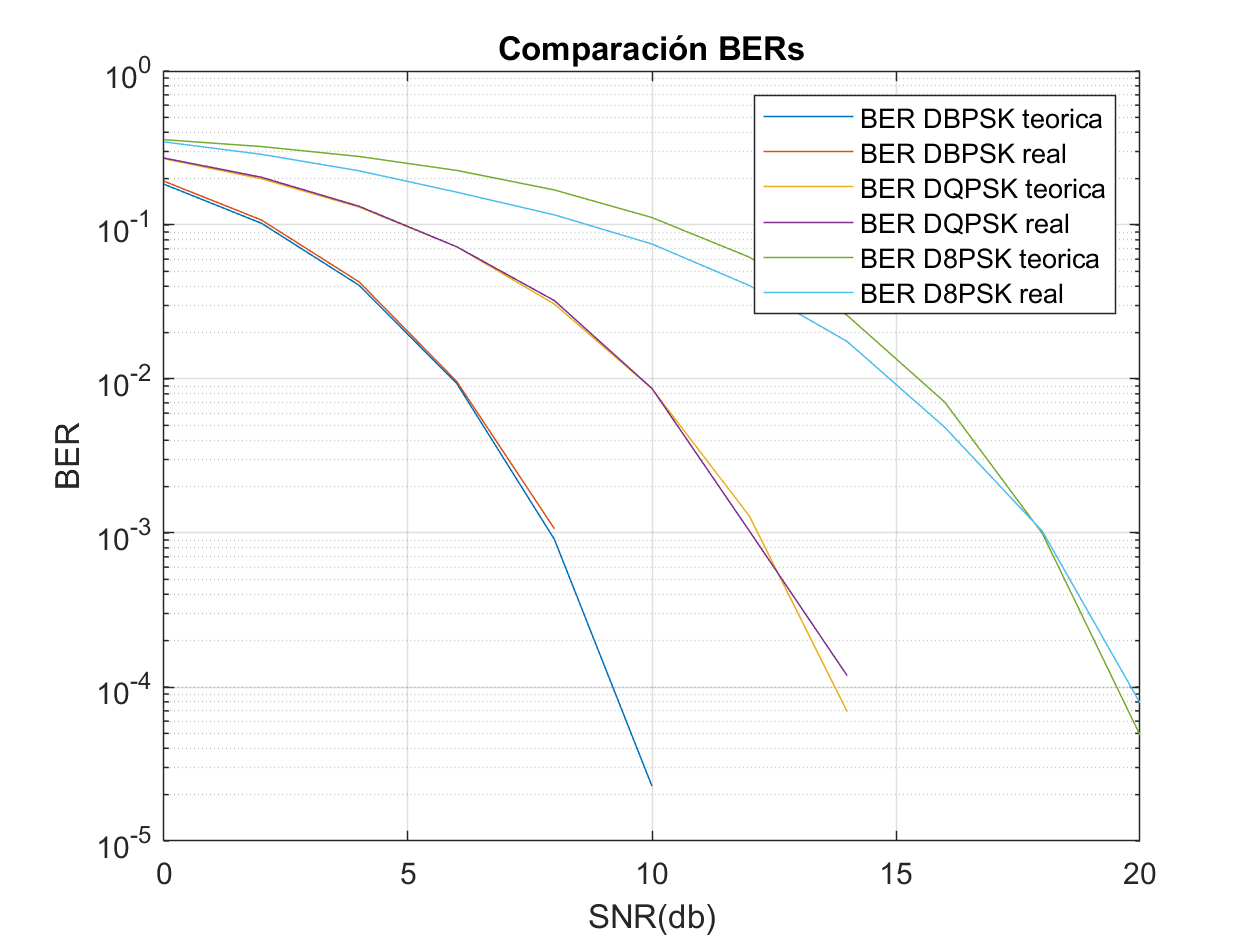

%canal h[n]=1. No hay atenuacion ni retardo en la señal TX producida por el
%canal. Solamente se añade AWGN.
% vector SNR
SNR_db = 0:2:35;
 % Cálculo del factor de ancho de banda . solo distribuir SNR en la parte
 % del espectro con portadoras (Nc)
 fb = 10*log10( (NFFT/2)/Nc);

%BER's teoricas de cada modulacion
BER_teor_DBPSK= DBPSK_BER(SNR_db);
BER_teor_DBPSK(find(BER_teor_DBPSK<1e-6))=NaN;
BER_teor_DQPSK= DQPSK_BER(SNR_db);
BER_teor_DQPSK(find(BER_teor_DQPSK<1e-6))=NaN;
BER_teor_D8PSK= D8PSK_BER(SNR_db);
BER_teor_D8PSK(find(BER_teor_D8PSK<1e-6))=NaN;
  
%bucle calculo BER_real_DBPSK
    for k=1:length(SNR_db)
        %y_noise=zeros(1, length(x_tx_DBPSK));
       y_noise_dbpsk=awgn(x_tx_DBPSK,SNR_db(k)-fb,'measured');
       y_noise_dqpsk=awgn(x_tx_DQPSK,SNR_db(k)-fb,'measured');
       y_noise_d8psk=awgn(x_tx_D8PSK,SNR_db(k)-fb,'measured');
       
        y_rx_noise_dbpsk=receptor(y_noise_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
        y_rx_noise_dqpsk=receptor(y_noise_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
        y_rx_noise_d8psk=receptor(y_noise_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
                
       
        diferencia_dbpsk=abs(txbits-y_rx_noise_dbpsk);
        diferencia_dqpsk=abs(txbits-y_rx_noise_dqpsk);
        diferencia_d8psk=abs(txbits-y_rx_noise_d8psk);
        
        BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
        BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
           
        BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
        BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
        
        BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
        BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
    end
    
%Representacion BER vs SNR para todos los tipos de modulacion
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

D8PSK + BER CONSTELACION PUNTOS MAS JUNTOS.

        2.   Inclusión de modelo de canal e inclusión de ecualizador

%canal variante en f. Corresponde a un filtro digital de k=9 posiciones en total (en el dominio del tiempo
% discreto):
h=[-0.1,0.3,-0.5,0.7,-0.9,0.7, -0.5, 0.3, -0.1]; % h=[a0...a8]; atenuaciones

   h[n] produce atenuación y retardo por reflexiones dentro de un canal multipath (retardo máximo 8) en la señal a transmitir.

s(t) -> TX

y(t)-> RX

y(t)=conv(s(t),h(t)) -> dominio discreto -> y[n]= conv(s[n],h[n]). 

y[n]=sum(att*s[n-k])- Seguir con esto en latex

H(f) en dbW

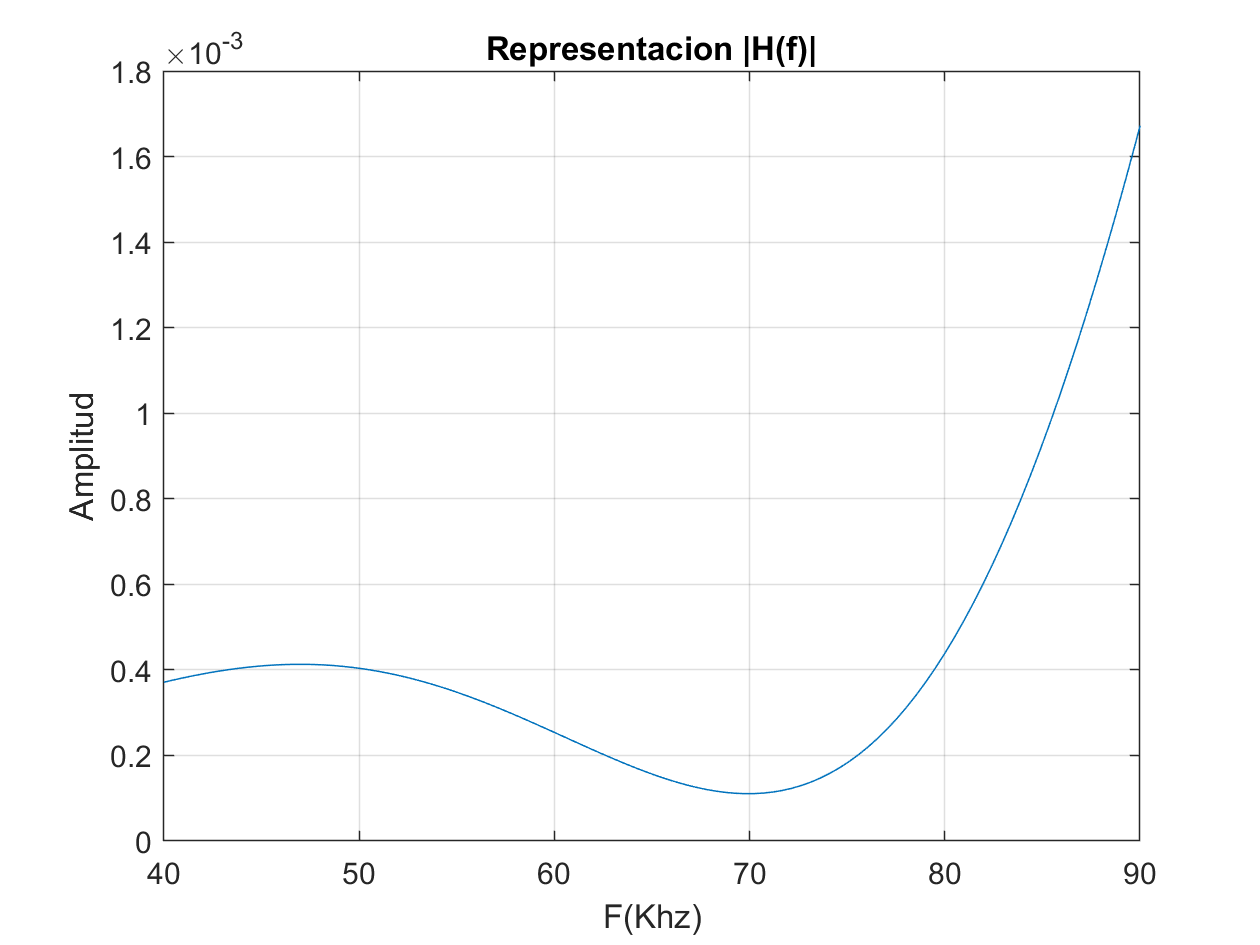

% vector f (paso Fs) -> mitad puntos NFFT espectro + y mitad -. Preguntar

% H(f) es la respuesta al impulso del canal -> FFT.
H=fft(h,NFFT)/NFFT;
f=linspace(-Fs/2,Fs/2, length(H));

%Representacion |H(f)| en el dominio de la frecuencia (unidades naturales)
figure
plot(f/1000,abs(fftshift(H)));
title('Representacion |H(f)|');
xlabel('F(Khz)');
xlim([40,90]);
ylabel('Amplitud');
grid on

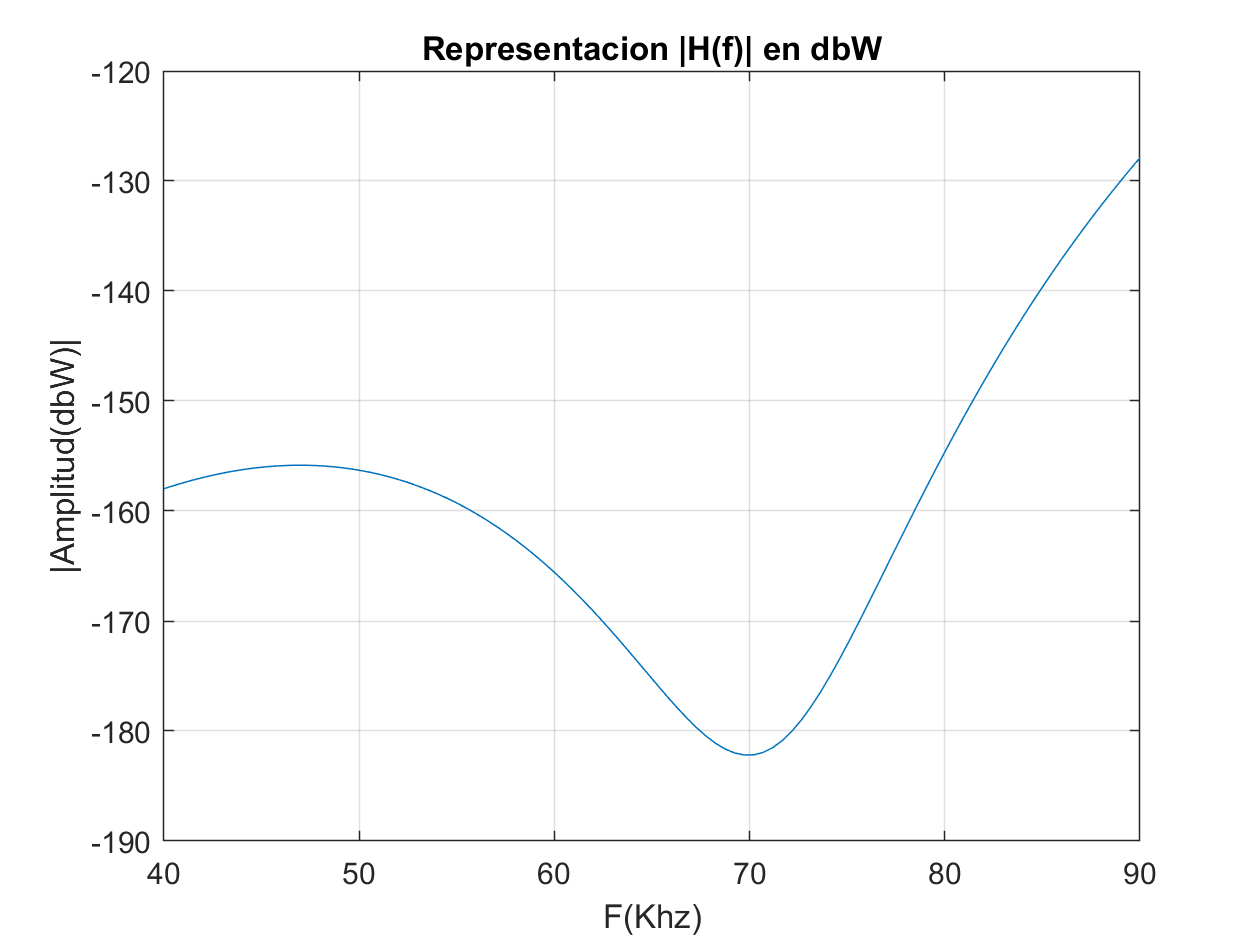

% Representacion |H(f)| el dominio de la frecuencia (db)
figure
plot (f/1000,20*log(abs(fftshift(H))))
title('Representacion |H(f)| en dbW');
xlabel('F(Khz)');
ylabel('|Amplitud(dbW)|');
grid on
xlim([40,90]);

%convolucion lineal sin cp y añadimos awgn
y_canal_DBPSK=conv(x_tx_DBPSK,h);
y_canal_DBPSK =y_canal_DBPSK(1:end-length(h)+1)

y_canal_DBPSK =    -3.4000   10.9368  -17.2858   20.3912  -21.1575    7.6495    5.7489   -7.7461    5.6883    0.3189   -8.8117    7.1122    1.9981   -6.2181    4.4233   -0.4856   -2.2852    3.3430   -4.5244    0.7420    7.0022   -4.7816   -3.4559    2.4298    0.1039    3.0886   -0.8831   -4.2372    2.3709    0.1258   -0.4772    2.8027   -2.4164   -0.5836    1.0554   -2.7875    4.0933    1.8139   -6.6790    2.2485    3.3432   -3.4695    1.4297    0.0234   -1.6160    3.5117   -2.1504   -3.2260    4.1917    1.2933


y_canal_DQPSK=conv(x_tx_DQPSK,h);
y_canal_DQPSK =y_canal_DQPSK(1:end-length(h)+1)

y_canal_DQPSK =    -1.0000    2.9373   -4.9457    8.9039  -13.3862    9.9284   -6.6606    7.8531   -0.3052   -6.8755    0.1648    2.2025    4.3246    1.1946   -9.3772    0.3793    8.1075   -2.8061   -0.1042    0.4832   -6.9620    4.9570    6.5448   -6.3012   -0.8918    0.7490   -2.9538    5.8484    2.5204   -6.4558   -1.4871    1.4997    2.5036    2.9059   -2.9774   -3.4892    0.0693    2.5834    3.5962   -2.4952   -3.1943    1.5955   -0.6224    1.5971    1.8332   -3.8434    2.2379    1.0739   -6.4055    4.2121



y_canal_D8PSK=conv(x_tx_D8PSK,h);
y_canal_D8PSK =y_canal_D8PSK(1:end-length(h)+1)

y_canal_D8PSK =    -2.7071    7.3701   -6.9806    2.2801   -1.4011   -5.9737   11.4363   -1.2764   -8.3659    4.0181   -0.0591   -0.8588    6.3064   -5.0921   -4.7760    5.4726   -0.1694    1.1162    1.4759   -7.2297    0.7971    6.6337   -0.9936   -1.9331   -2.5460   -0.3625    4.6306   -0.8703   -1.2420    1.3238   -3.9521    0.6903    4.6085   -1.3580   -0.7459   -1.8253   -1.7747    4.7949    0.3326   -2.5074    0.9026   -2.5758    1.5280    2.9312   -3.7734    2.7861    0.2220   -6.3459    6.4590    1.0464


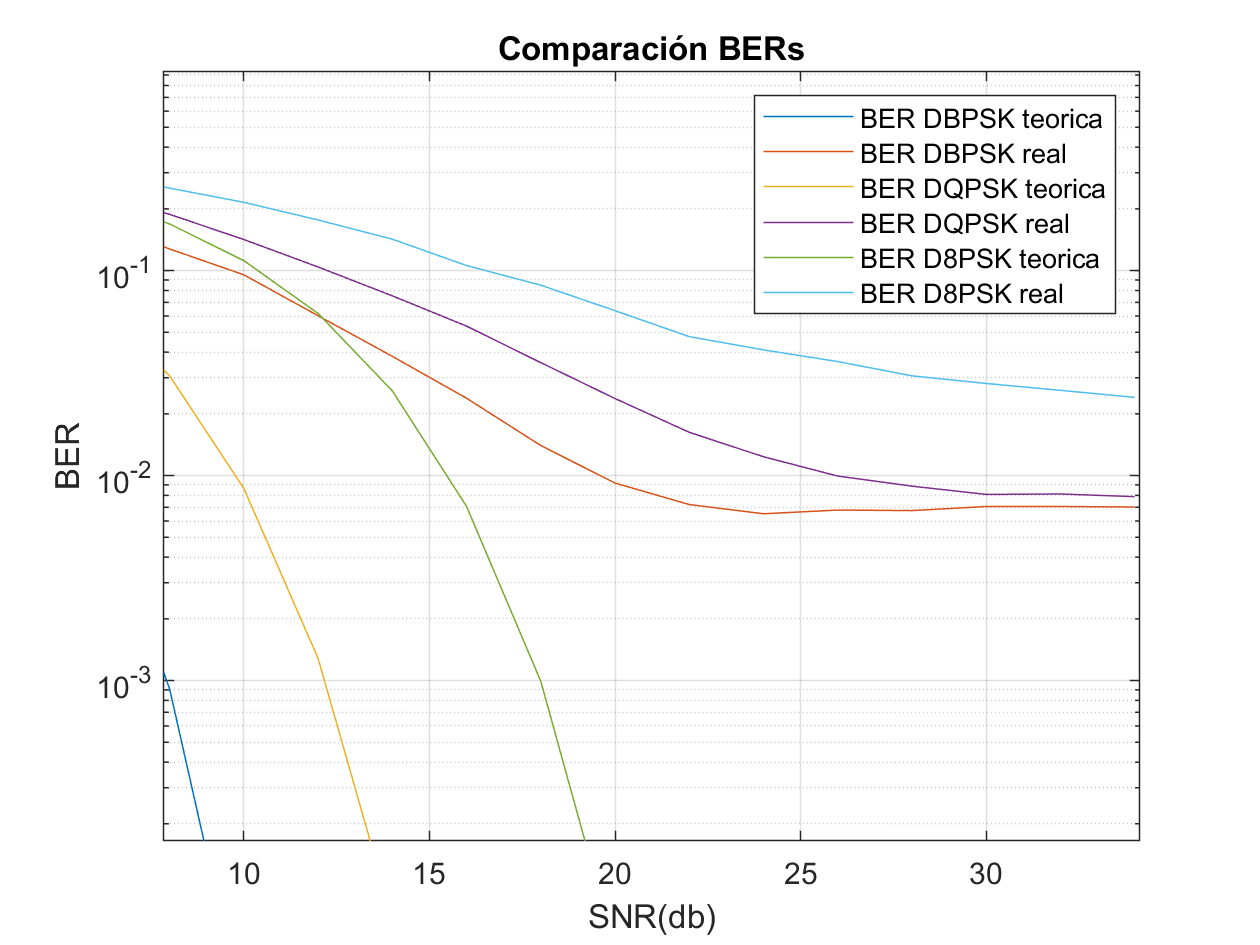

%añadimos el ruido
 for k=1:length(SNR_db)
        %y_noise=zeros(1, length(x_tx_DBPSK));
       y_noise_canal_dbpsk=awgn(y_canal_DBPSK,SNR_db(k)-fb,'measured');
       y_noise_canal_dqpsk=awgn(y_canal_DQPSK,SNR_db(k)-fb,'measured');
       y_noise_canal_d8psk=awgn(y_canal_D8PSK,SNR_db(k)-fb,'measured');
       
        y_rx_noise_canal_dbpsk=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
        y_rx_noise_canal_dqpsk=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
        y_rx_noise_canal_d8psk=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
                
       
        diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk);
        diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk);
        diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk);
        
        BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
        BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
           
        BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
        BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
        
        BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
        BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
 end
 
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

FONDO DE BER EN TORNO 10^-2. eq lo quitara. BPSK MENOR BER

%incluir prefijo ciclico ncp=48. asi se puede recuperar el canal con la
%inversa (problema FFT)
x_tx_DBPSK_exten = [(length(x_tx_DBPSK)-Ncp+1:length(x_tx_DBPSK)) x_tx_DBPSK]
